clearvars
%{
% Define folder path containing images
folderPath = 'Mushrooms/*';

% Create an imageDatastore for the folder
imds = imageDatastore(folderPath, 'FileExtensions', '.jpg');

% Loop through each image and check its size
for i = 1:numel(imds.Files)
    % Read the image
    img = readimage(imds,i);
    
    % Get the size of the image
    [h, w, c] = size(img);
    
    % Check if the image is 300x300
    if h ~= 300 || w ~= 300 || c ~= 3
        fprintf('Image %s is not 300x300\n', imds.Files{i});
    end
end
%}

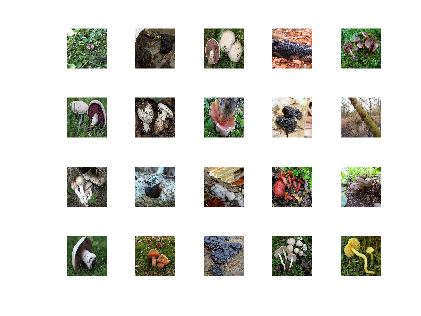

%getting all images and labels from main folder 
mushroomsetfullpath = fullfile("Mushrooms/");
imds = imageDatastore(mushroomsetfullpath, ...
    'IncludeSubfolders',true,'LabelSource','foldernames');
figure;
perm = randperm(5000,20);
for i = 1:20
    subplot(4,5,i);
    imshow(imds.Files{perm(i)});
end

%getting count of images per label
labelCount = countEachLabel(imds)

labelCount = 12×2 table
       Label       Count
    ___________    _____

    Agaricus        976 
    Amanita         750 
    Boletus        1071 
    Cortinarius     836 
    Entoloma        839 
    Exidia          435 
    Hygrocybe       744 
    Inocybe         618 
    Lactarius      1087 
    Pluteus         441 
    Russula        1073 
    Suillus         661 


%splitting images into training and validation
[imdsTrain,imdsValidation] = splitEachLabel(imds,0.85,'randomize');
Tarinlabelcount = countEachLabel(imdsTrain)

Tarinlabelcount = 12×2 table
       Label       Count
    ___________    _____

    Agaricus        830 
    Amanita         638 
    Boletus         910 
    Cortinarius     711 
    Entoloma        713 
    Exidia          370 
    Hygrocybe       632 
    Inocybe         525 
    Lactarius       924 
    Pluteus         375 
    Russula         912 
    Suillus         562 


%defining the network
%{ 
%Gave 29 accuracy
layers = [
    imageInputLayer([300 300 3])
    
    convolution2dLayer(20,8,'Padding','same')
    batchNormalizationLayer
    reluLayer
    
    maxPooling2dLayer(2,'Stride',8)
    
    convolution2dLayer(10,16,'Padding','same')
    batchNormalizationLayer
    reluLayer
    
    maxPooling2dLayer(2,'Stride',16)
    
    convolution2dLayer(5,32,'Padding','same')
    batchNormalizationLayer
    reluLayer

    maxPooling2dLayer(2,'Stride',32)
    
    fullyConnectedLayer(12)
    softmaxLayer
    classificationLayer
    ];
%}

layers = [    
    imageInputLayer([300 300 3])

    convolution2dLayer(32,3,'Padding','same')
    batchNormalizationLayer
    reluLayer
    
    maxPooling2dLayer(2,'Stride',2)
    
    convolution2dLayer(64,6,'Padding','same')
    batchNormalizationLayer
    reluLayer
    
    maxPooling2dLayer(2,'Stride',2)
    
    convolution2dLayer(128,8,'Padding','same')
    batchNormalizationLayer
    reluLayer

    maxPooling2dLayer(2,'Stride',2)
    
    convolution2dLayer(256,12,'Padding','same')
    batchNormalizationLayer
    reluLayer
    
    maxPooling2dLayer(2,'Stride',2)
    
    fullyConnectedLayer(512)
    reluLayer
    dropoutLayer(0.5)
    
    fullyConnectedLayer(256)
    reluLayer
    dropoutLayer(0.5)
    
    fullyConnectedLayer(12)
    softmaxLayer
    classificationLayer
    ];

options = trainingOptions('sgdm', ...
    'InitialLearnRate',0.01, ...
    'MaxEpochs',20, ...
    'Shuffle','every-epoch', ...
    'ValidationData',imdsValidation, ...
    'ValidationFrequency',30, ...
    'MiniBatchSize',32, ...
    'Verbose',false, ...
    'Plots','training-progress');

%training with created network and training data
net = trainNetwork(imdsTrain,layers,options);

YPred = classify(net,imdsValidation);
YValidation = imdsValidation.Labels;

accuracy = sum(YPred == YValidation)/numel(YValidation)